# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Paper3Fig/']; % V1D2
close all

## 2. Test for different x for E and I; yE and yI kept as 1 -- All killed are folded back

first get basic function information

Too time comsuming. --->> using HPC

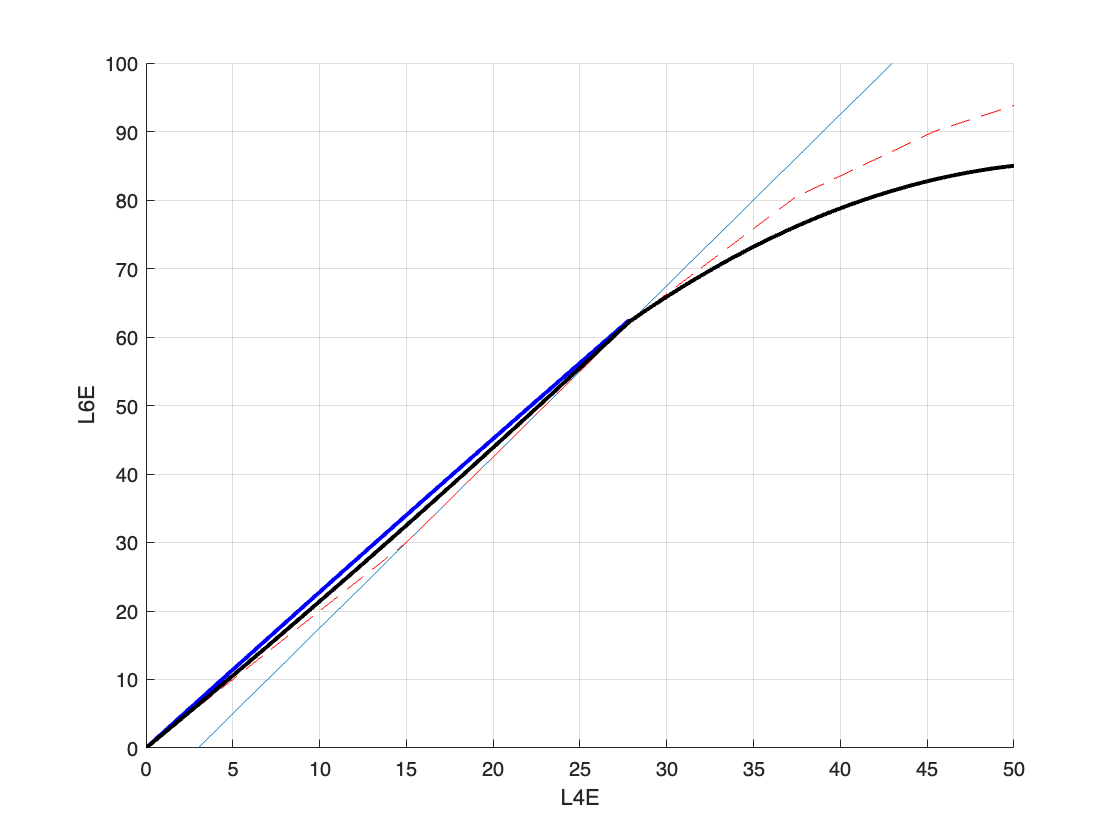

close all
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
%L6pars{2} = {2.5,3,[28; 31.5;37.4],[62.5; 69; 80.4],'quadratic'};
%L6pars{2} = {2.5,3,62.5,86,80.4,106,90};
L6pars{5} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,32.5],[28 32 50],[69 85]}};

L6pars{4} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,34],[28 32 50],[69 85]}};
L6pars{3} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 28],[1,34]}};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20],{[8 21.5 25],[0.04,0]}}}; % {[10 20 25],[0.04,0.02]}
L6pars{1} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20]}};
%L6pars{1} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
xx = 0:0.1:50;
yy = L6Convert(xx, L6pars{1});
zz = L6Convert(xx, L6pars{2});
ww = L6Convert(xx, L6pars{4});
rr = L6Convert(xx, L6pars{5});
figure(99)
hold on
grid on
plot(xx,2.5*(xx-3))
plot(xx,yy,'r--')
%plot(xx,zz,'k-','LineWidth',2)
plot(xx,ww,'b-','LineWidth',2)
plot(xx,rr,'k-','LineWidth',2)

ylim([0 100])
xlabel('L4E');ylabel('L6E')

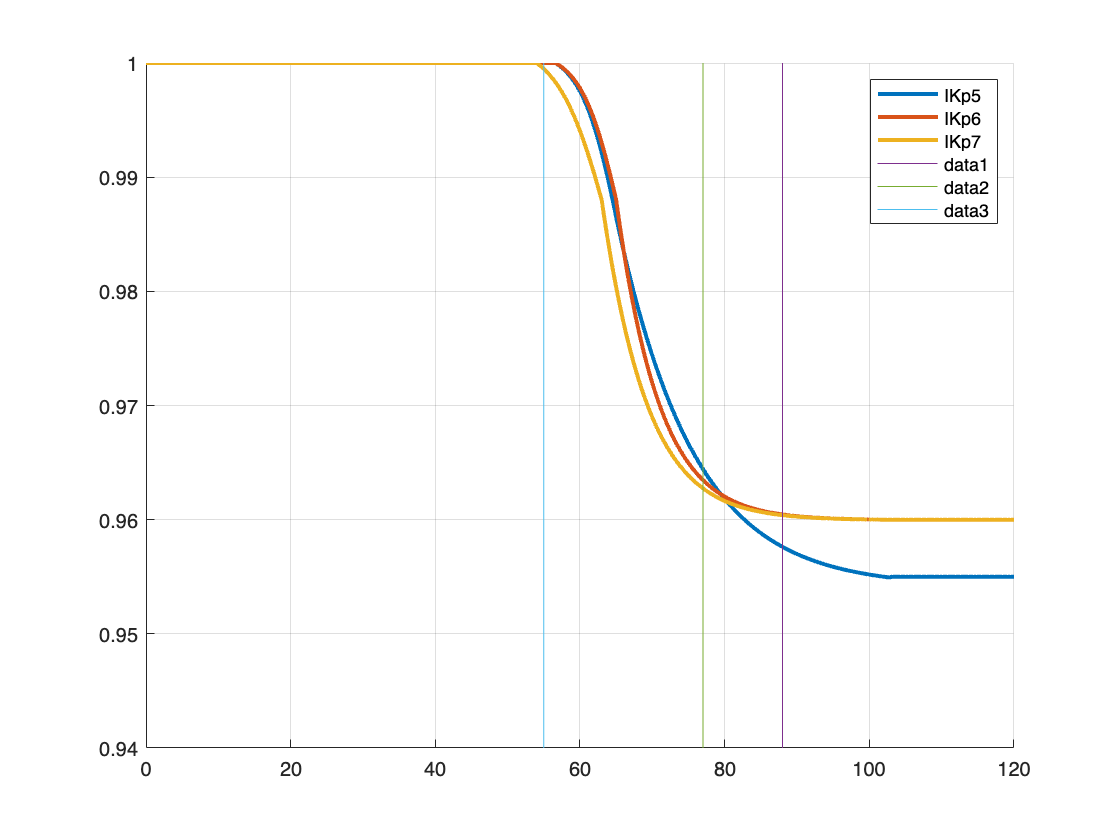


% Inhibition saturation info
IKp1.Thrsld1 = 56.6; IKp1.Thrsld2 = 68.6;
IKp1.Highist = 115;  IKp1.Slope = 0.95; % this is for new rule: multiplicative saturation
Isaturation = true;
IKp1.Mode = 'multisigmoid'; % or 'linear'
IKp1.IntaH = 5.5; IKp1.IntaL = -1;
IKp1.IntbL = 3; IKp1.IntbH = 0.5; % one side start from 3. another side start from 6

IKp2.Thrsld1 = 56.6; IKp2.Thrsld2 = 65;
IKp2.Highist = 103;  IKp2.Slope = 0.949; % this is for new rule: multiplicative saturation
IKp2.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp2.Mode = 'multisigmoid'; % or 'linear'
IKp2.IntaH = 4.5; IKp2.IntaL = -2.5;
IKp2.IntbL = 3.4; IKp2.IntbH = -0.3; % one side start from 3. another side start from 6

IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKp4.Thrsld1 = 56.6; IKp4.Thrsld2 = 65;
IKp4.Highist = 103;  IKp4.Slope = 0.9525; % this is for new rule: multiplicative saturation
IKp4.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp4.Mode = 'multisigmoid'; % or 'linear'
IKp4.IntaH = 5; IKp4.IntaL = -2.5;
IKp4.IntbL = 3.4; IKp4.IntbH = -0.3; % one side start from 3. another side start from 6

IKp5.Thrsld1 = 56.6; IKp5.Thrsld2 = 65;
IKp5.Highist = 103;  IKp5.Slope = 0.955; % this is for new rule: multiplicative saturation
IKp5.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp5.Mode = 'multisigmoid'; % or 'linear'
IKp5.IntaH = 6.3; IKp5.IntaL = -2.5;
IKp5.IntbL = 3.4; IKp5.IntbH = -0.3; % one side start from 3. another side start from 6

IKp6.Thrsld1 = 56.6; IKp6.Thrsld2 = 65;
IKp6.Highist = 103;  IKp6.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp6.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp6.Mode = 'multisigmoid'; % or 'linear'
IKp6.IntaH = 9.3; IKp6.IntaL = -2.5;
IKp6.IntbL = 3.4; IKp6.IntbH = -0.3; % one side start from 3. another side start from 6

IKp7.Thrsld1 = 54; IKp7.Thrsld2 = 63;
IKp7.Highist = 103;  IKp7.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp7.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp7.Mode = 'multisigmoid'; % or 'linear'
IKp7.IntaH = 9.3; IKp7.IntaL = -2.5;
IKp7.IntbL = 2.9; IKp7.IntbH = -0.3; % one side start from 3. another side start from 6

figure(100)
xx = 0:0.1:120;
IKpAll = {IKp1,IKp2,IKp3,IKp4,IKp5,IKp6,IKp7};
for IkpInd = 5:length(IKpAll)
    [yy1,fac1] = InhMulp(xx,IKpAll{IkpInd});
    hold on
    plot(xx,fac1,'LineWidth',2,'DisplayName',sprintf('IKp%d',IkpInd))
end
%plot(60:100,1-(0:40)*0.05/40)
yyz = 0.94:0.01:1;
plot(88*ones(size(yyz)),yyz)
plot(77*ones(size(yyz)),yyz)
plot(55*ones(size(yyz)),yyz)
grid on
axis([0 120 0.94 1])
legend


L6parId = 5;
IkpInd = 7;
IKpUse = IKpAll{IkpInd};
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'};

#### Fig2: full contrast FrE maps

close all
lgnSF = 2.5;
Conn_Reduc_TestS = 6; Conn_Reduc_TestC = 4;
N_HCOutY = 8; N_HCOutX = 4;
FrEBG = 4.3;
%L6parId = 4;
%IKpUse = IKp3;

if strcmp(L6pars{L6parId}{end},'quadratic')
    L6Comment = sprintf('%s',L6pars{L6parId}{end})
elseif iscell(L6pars{L6parId}{end})
    L6Comment = sprintf('LowModi3');
    if length(L6pars{L6parId}{end}) == 4
        L6Comment = sprintf('LowHighQuadr5')
    end
    if iscell(L6pars{L6parId}{end}{end})
        L6Comment = sprintf('ContrTweak3');
    end
else
    L6Comment = sprintf('linear')
end

L6Comment = 'LowHighQuadr5'


IkpComment = sprintf('IKp%d',IkpInd);
ContrStr = '';

lgnTFAll = [2 4 10 16 24];

lgnTF =  10;%[2 4 10 16 24]
MonocuFlag = false;

SaveStr = ['Bino' Comment L6Comment IkpComment];
loadStrUse = sprintf('%s_LGNSF%.1fTF%d%s-xE%.1fyE%.1f-Sd%.1fCd%.1f',...
    loadStr,lgnSF,lgnTF,ContrStr, ParaEx, ParaEy,Conn_Reduc_TestS,Conn_Reduc_TestC);

load([SaveToFolder sprintf('NESSs-RLGNL6-EIdep_%s.mat',loadStrUse)],...
    'LDEOutAll')

Fig2 = figure("Name",sprintf('NESS-Fig2_%s',SaveStrUse),...
    'units','normalized','outerposition',[0,0,1,1]);
ha = tight_subplot(5,5,[.04 .015],[.05 .05],[.05 .1]);
for TestId = 1:TestNum
    if NANFlag(TestId)
        continue
    end
    axes(ha(TestId));
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    %title(sprintf('P(cross)=%.1f, P(return)=%.2f',...
    %    TestExSeq(TestId),(1-TestExSeq(TestId)) * TestEySeq(TestId)),...
    %    'Interpreter','tex','FontSize',15)
    axes(ha(TestId));
    axis([0.5 40.5 0.5 40.5])
    axis square
    caxis([0 35]);
    colorbar off
    if mod(TestId,5) == 0
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
        set(cbr1,'FontSize',13)
        set(cbr1,'xtick',0:5:35)
        ylabel(cbr1,'sp/s')
    end
    title(['$$',sprintf('%.1f',7.5*(TestId-1)),'^{\circ}$$'],'Interpreter','latex','FontSize',14)
    %     subplot 122
    %     ShowField_Rec(LDEOutAll{TestId}{end}.I,...
    %         1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
    %     title("FrI")

end

Save and Print Figs

FigName1 = sprintf('Fig2B-original');
savefig(Fig2,[FigurePaperPath FigName1 '.fig']);

Fig2.PaperUnits = 'centimeters';
Fig2.PaperSize = [36,28];
Fig2.PaperOrientation = "landscape";
exportgraphics(Fig2,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

#### Fig 2&3 gratings production

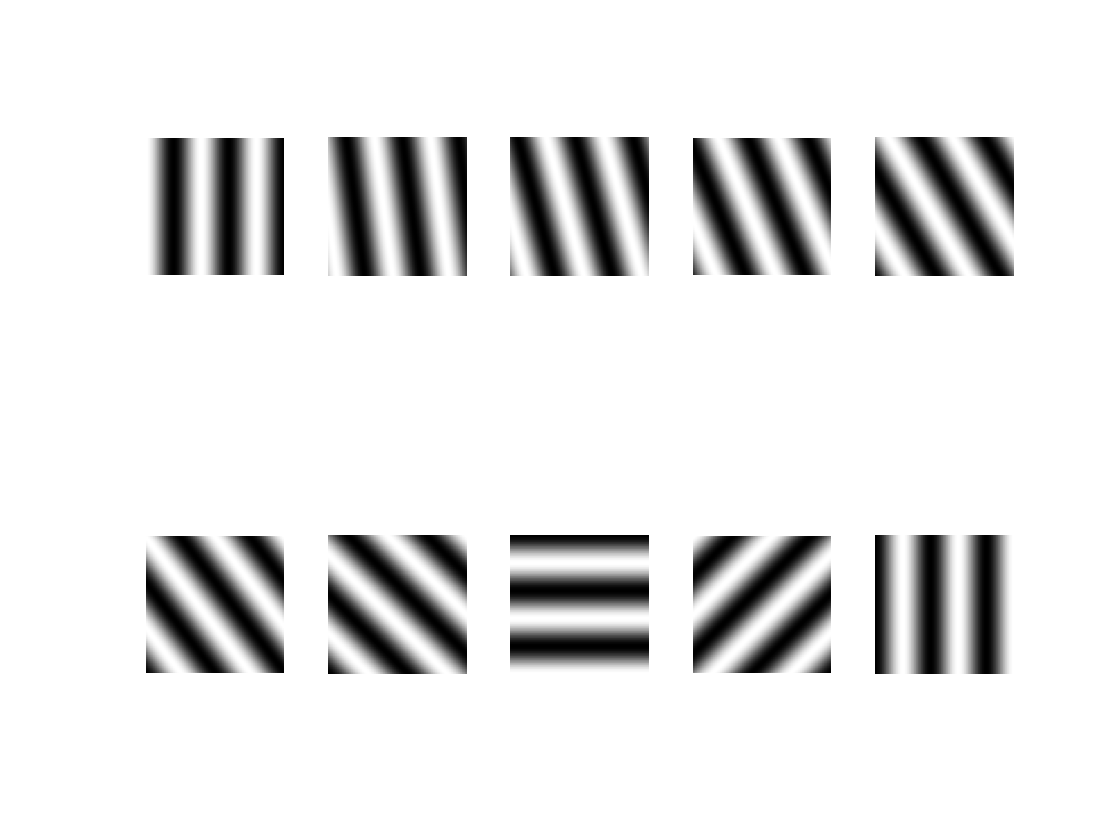

C = 1

C = 1

C = 1

C = 1

C = 1

C = 1

C = 1

C = 1

C = 1

C = 1

close all
figure
x_int = -0.5:0.005:0.5; y_int = -0.5:0.005:0.5;
[x1,x2] = meshgrid(x_int,y_int); 
tL = [0 25 50]; % in ms

%CAll = [0 19 40 66 100]/100;%
%CAll = [CAll,CAll];
CAll = ones(1,10);
C = 1;
g_abs = 2.5; f = 10/1e3; phi = 0; L0 = 1;
%plotId = 1;
ThetaUse = [0:7.5:45,90:45:180]; % [zeros(1,5),60*ones(1,5)]; %
for plotId = 1:10
    theta = ThetaUse(plotId)/180*pi; % 0-pi
    g = [cos(theta);sin(theta)];
    g = g/norm(g) * g_abs;

    C = CAll(plotId)
    L = @(x,y,t) ... % x and y as above; t in second
        (C * sin(-2*pi*(g(1)*x + g(2)*y) + 2*pi*f*t + phi) + 1) * L0;
        subplot(2,5,plotId)
        imagesc(-1:0.005:1,-1:0.005:1,L(x1,x2,0))
        set(gca,'YDir','Normal'); colormap gray; % colorbar
        caxis([0 2])
        axis([-1 1 -1 1]) 
        axis square
       
        axis off

    %plotId = plotId + 1;
end

#### Fig7: Compute binocularity from tuning curve

close all
lgnSF = 2.5;
Conn_Reduc_TestS = 5; Conn_Reduc_TestC = 5;
% four types of BI definition
BIcomment = {'mo-mb','mo-mm','oargmb-mb','oargmm-mm','final-BI','final-BMI','moMax','BMI-hist'}

BIcomment = 1×8 cell array
    {'mo-mb'}    {'mo-mm'}    {'oargmb-mb'}    {'oargmm-mm'}    {'final-BI'}    {'final-BMI'}    {'moMax'}    {'BMI-hist'}


for BIid = 8

    close all
    N_HCOutY = 8; N_HCOutX = 4;

    FrEBG = 4.3;
    %L6parId = 4;
    %IKpUse = IKp3;

    if strcmp(L6pars{L6parId}{end},'quadratic')
        L6Comment = sprintf('%s',L6pars{L6parId}{end})
    elseif iscell(L6pars{L6parId}{end})
        L6Comment = sprintf('LowModi3');
        if length(L6pars{L6parId}{end}) == 4
            L6Comment = sprintf('LowHighQuadr5')
        end
        if iscell(L6pars{L6parId}{end}{end})
            L6Comment = sprintf('ContrTweak3');
        end
    else
        L6Comment = sprintf('linear')
    end

    IkpComment = sprintf('IKp%d',IkpInd);
    ContrStr = '';

    lgnTFAll = [2 4 10 16 24];
    MaxFrPixA = zeros(size(lgnTFAll));
    MaxFrPixD = zeros(size(lgnTFAll));

    lgnTF =  10;%[2 4 10 16 24]

    Fig6 = figure('Name','BinoInd','units','normalized',...
        'outerposition',[0,0,1,0.3]); % 0.7 0.8
    ha = tight_subplot(1,5,[.02 .015],[.1 .1],[.1 .1]);
    plotId = 1;
    for L6BinoIndex = 0%:0.1:0.3
        for  ParaEx = 0:0.25:1 % 1
            ParaEy = 1;
            TCAllPix = {};
            % DataStrUse = sprintf('%s_RealLGNSF%.1fTF%d-L6Real%s_L4Idepprl%.1fm%.1fh%.1f-Sd%.1fCd%.1f',...
            %     SaveStr,lgnSF,lgnTF, L6Comment, IKpUse.Thrsld1,IKpUse.Thrsld2, IKpUse.Highist,Conn_Reduc_TestS,Conn_Reduc_TestC);
            %
            %
            % load([SaveToFolder sprintf('RealLGN-NESSs-ModiIdep_%s.mat',SaveStrUse)],...
            %     'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','AngleTestAll')
            for MonocuFlag = [true,false]
                if MonocuFlag
                    SaveStr = ['Mono' Comment L6Comment IkpComment];
                    DataStrUse = sprintf('%s_LGNSF%.1fTF%d%s-L6BinoInd%.1f-xE%.1fyE%.1f-Sd%.1fCd%.1f',...
                        SaveStr,lgnSF,lgnTF,ContrStr, L6BinoIndex, ParaEx, ParaEy,Conn_Reduc_TestS,Conn_Reduc_TestC);

                    load([SaveToFolder sprintf('NESSs-RLGNL6-EIdep-L6BinoTest_%s.mat',DataStrUse)],...
                        'LDEOutAll',...
                        'AngleTestAll','L6pars')
                else
                    SaveStr = ['Bino' Comment L6Comment IkpComment];
                    loadStrUse = sprintf('%s_LGNSF%.1fTF%d%s-xE%.1fyE%.1f-Sd%.1fCd%.1f',...
                        SaveStr,lgnSF,lgnTF,ContrStr, ParaEx, ParaEy,Conn_Reduc_TestS,Conn_Reduc_TestC);

                    load([SaveToFolder sprintf('NESSs-RLGNL6-EIdep_%s.mat',loadStrUse)],...
                        'LDEOutAll')
                end




                [xAll,yAll] = meshgrid(1:10,1:10);
                PixAll = [xAll(:),yAll(:)];

                if MonocuFlag
                    TCDriveFlagAll = [true,false]; %[t,f]
                else
                    TCDriveFlagAll = true;
                end
                TuningCurvePlotAll = cell(length(PixAll),length(TCDriveFlagAll));
                for DriveId = 1:length(TCDriveFlagAll)
                    TCDriveFlag = TCDriveFlagAll(DriveId);
                    if TCDriveFlag
                        CtgrPix = PixAll;
                        ODStr = 'Dr';
                    else
                        CtgrPix = [xAll(:),21-yAll(:)];
                        ODStr = 'NoDr';
                    end

                    % Do the 2*2 HC and print pixel texts
                    Patt = LDEOutAll{1}{end};
                    EPatt = Patt.S*(1-CplxR) + Patt.C*CplxR;

            Print constritions only when binocular

                    if ~MonocuFlag && ParaEx == 0 && DriveId == 1
                        SMap = reshape(Patt.S,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        CMap = reshape(Patt.C,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        EMap = reshape(EPatt, N_HCOutY*NPixY,N_HCOutX*NPixX);
                        IMap = reshape(Patt.I,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        optY = floor(NPixY/2); optX = NPixX;
                        ortY = floor(NPixY/2); ortX = 1;
                        Eopt = EMap(optY,optX); Eort = EMap(ortY,ortX);
                        Sopt = SMap(optY,optX); Sort = SMap(ortY,ortX);
                        Copt = CMap(optY,optX); Cort = CMap(ortY,ortX);
                        Iopt = IMap(optY,optX); Iort = IMap(ortY,ortX);
                        fprintf(['Eopt=%.1fHz; Copt/Sopt=%.1f; Iopt/Eopt=%.1f; Eort=%.1fHz\n',...
                            'Eort=%.1fHz; Cort/Sort=%.1f; Iort/Eort=%.1f; Eopt/Eort=%.1f'],...
                            Eopt,        Copt/Sopt,      Iopt/Eopt,      Eort,...
                            Eort,        Cort/Sort,      Iort/Eort,      Eopt/Eort)
                    end

Tuning curves

                    AnglePlot = [AngleTestAll(floor(end/2)+1:end-1),...
                        AngleTestAll(1:floor(end/2)), ...
                        AngleTestAll(floor(end/2)+1)];
                    AngleUnique = 1:length(AnglePlot);
                    for PixInd = 1:length(CtgrPix)
                        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
                        TuningCurve = zeros(size(AngleTestAll));
                        for angId = 1:length(TuningCurve)
                            PattS = LDEOutAll{angId}{end}.S;
                            PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
                            PattC = LDEOutAll{angId}{end}.C;
                            PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
                            TuningCurve(angId) = ...
                                PattS(y,x) * (1-CplxR) + ...
                                PattC(y,x) * CplxR;
                        end
                        TuningCurvePlot = ...
                            [TuningCurve(floor(end/2)+1:end-1),...
                            TuningCurve(1:floor(end/2)), ...
                            TuningCurve(floor(end/2)+1)];
                        TuningCurvePlotAll{PixInd,DriveId} = TuningCurvePlot;
                    end


                    xtickAng = AnglePlot;
                    xtickLab = cell(size(xtickAng));
                    for xticInd = 1:length(xtickAng)
                        if mod(xticInd,4) == 1
                            xtickLab{xticInd} = num2str(xtickAng(xticInd));
                        end
                    end
                end
                TCAllPix = [TCAllPix,TuningCurvePlotAll];
            end

            BinocuIndex = zeros(length(CtgrPix),1);
            BinoMHist = zeros(length(CtgrPix),1);
            for PixId = 1:length(CtgrPix)
                NoDirTC = TCAllPix{PixId,2};
                BinoDirTC = TCAllPix{PixId,3};
                MonoDirTC = TCAllPix{PixId,1};
                switch BIid
                    case 1
                        BinocuIndex(PixId) = ...
                            (max(NoDirTC,[],'all')-FrEBG)/(max(BinoDirTC,[],'all')-FrEBG);
                    case 2
                        BinocuIndex(PixId) = ...
                            (max(NoDirTC,[],'all')-FrEBG)/(max(MonoDirTC,[],'all')-FrEBG);
                    case 3
                        maxId = find(BinoDirTC == max(BinoDirTC,[],'all'));
                        BinocuIndex(PixId) = (NoDirTC(maxId(1))-FrEBG)/(BinoDirTC(maxId(1))-FrEBG);
                    case 4
                        maxId = find(MonoDirTC == max(MonoDirTC,[],'all'));
                        BinocuIndex(PixId) = (NoDirTC(maxId(1))-FrEBG)/(MonoDirTC(maxId(1))-FrEBG);
                    case 5 % finally -- the BI
                        Mres = max(MonoDirTC,[],'all')-FrEBG;
                        maxId = find(MonoDirTC == max(MonoDirTC,[],'all'));
                        Ores = (NoDirTC(maxId(1))-FrEBG);

                        BinocuIndex(PixId) = (1-(Mres-Ores)/(Mres + Ores))/2;
                    case 6 % finally -- the BMI
                        Mres = max(MonoDirTC,[],'all')-FrEBG;
                        Bres = max(BinoDirTC,[],'all')-FrEBG;
                        BinocuIndex(PixId) = (Bres-Mres)/(Bres + Mres);
                    case 7 % max fr for o input
                        Ores = max(NoDirTC,[],'all')-FrEBG;            
                        BinocuIndex(PixId) = Ores;
                    case 8
                        Mres = max(MonoDirTC,[],'all')-FrEBG;
                        Bres = max(BinoDirTC,[],'all')-FrEBG;
                        BinoMHist(PixId) = Mres/Bres;
                end
            end

            axes(ha(plotId));
            if BIid < 8
                imagesc(reshape(BinocuIndex,NPixY,NPixX))
                colormap(jet)
                caxis([0 0.8])
                switch BIid
                    case 5
                        caxis([0 0.4])
                    case 6
                        caxis([-0.2 0.2])
                    case 7
                        caxis([0 10])
                end
                %caxis([0.7 1.3])
                set(gca,'xtick','','ytick','')
                axis square

                Pos1 = get(gca,'Position');

                if mod(plotId,5) == 0
                    cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.02  Pos1(2)  0.015  Pos1(4)]);
                    set(cbr1,'FontSize',18)
                    switch BIid
                        case 5
                            set(cbr1,'Ticks',0:0.1:0.4)
                        case 6
                            set(cbr1,'Ticks',-0.2:0.1:0.2)
                    end
                end

            else % for the special histogram
                hist(BinoMHist,0.65:0.05:1.35)
                hold on
                plot(ones(size(0:50)),0:50,'r--')
                xlabel('m/b')
                ylim([0 45])
                grid on

                if mod(plotId,5) ~= 1
                    set(gca,'yticklabel','')
                end
            end

            if plotId <=5
                title(sprintf('P(cross) = %.2f',ParaEx))
            end

            if mod(plotId,5) == 1
                ylabel(sprintf('%.1f',L6BinoIndex))
            end

            plotId = plotId +1;
        end
    end

Save figures

    FigName1 = sprintf('Fig8_%s',BIcomment{BIid});
    savefig(Fig6,[FigurePaperPath FigName1 '.fig']);


Print Figs

    Fig6.PaperUnits = 'centimeters';
    Fig6.PaperSize = [36,28];
    Fig6.PaperOrientation = "landscape";
    exportgraphics(Fig6,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
    close all
end

L6Comment = 'LowHighQuadr5'

Eopt=29.9Hz; Copt/Sopt=4.9; Iopt/Eopt=2.8; Eort=5.4Hz
Eort=5.4Hz; Cort/Sort=2.8; Iort/Eort=5.0; Eopt/Eort=5.6